Prepared by

*Asif Newaz*

*Lecturer, EEE, IUT *

**Contrast adjustment**

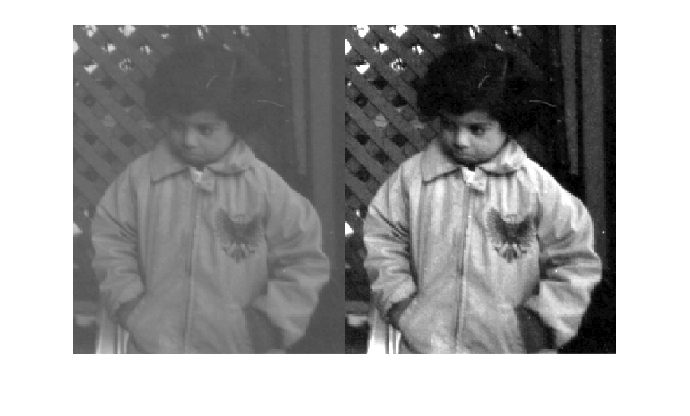

I = imread('pout.tif');
J = imadjust(I);
montage({I,J})

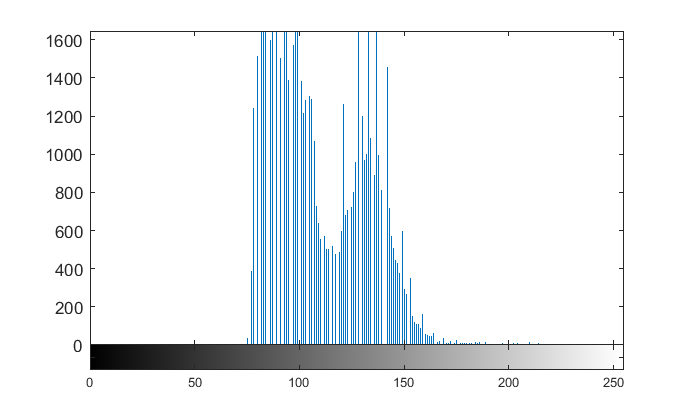

imhist(I)

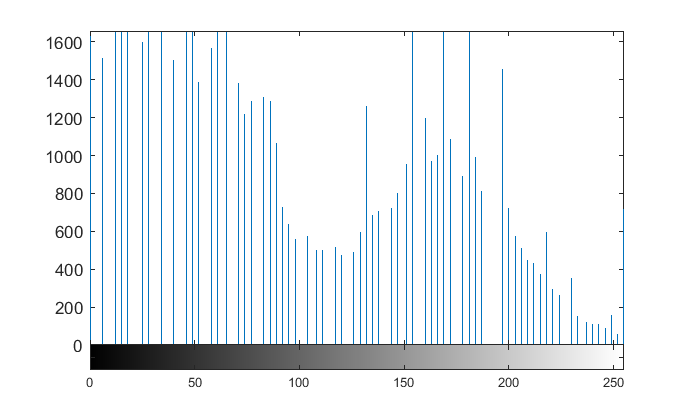

imhist(J)

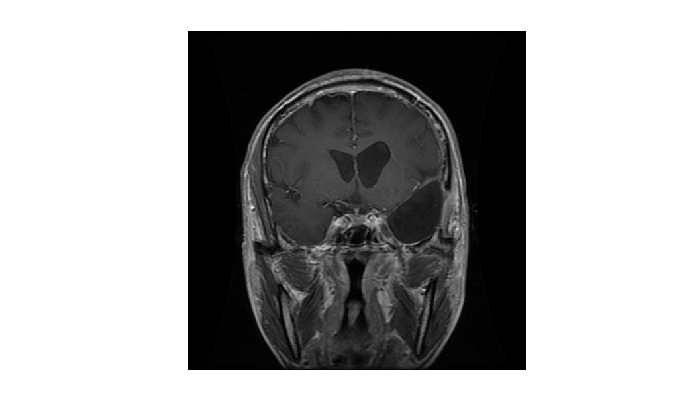

img= imread("Tr-gl_0011.jpg");
img_gray= rgb2gray(img);
imshow(img_gray)

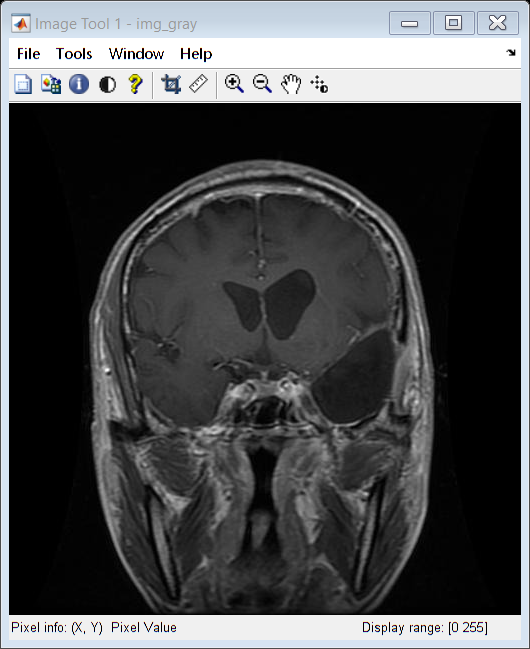

imtool(img_gray)

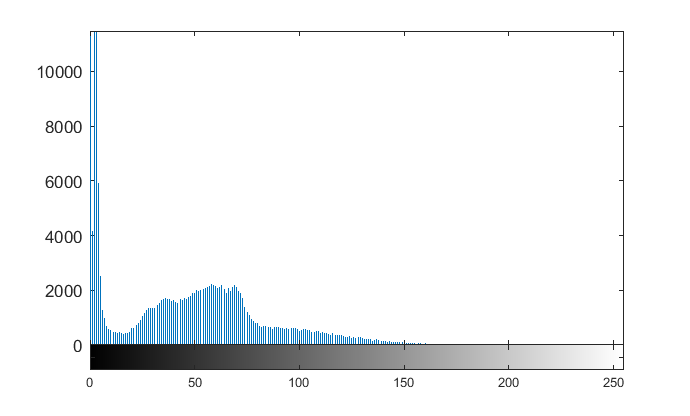

imhist(img_gray)

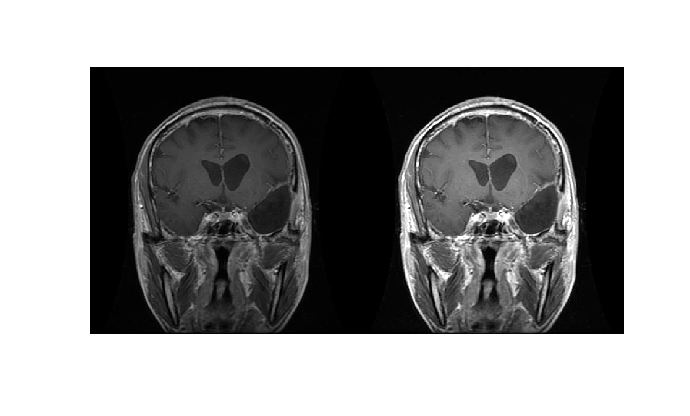

img_adj= imadjust(img_gray);
montage({img_gray, img_adj})

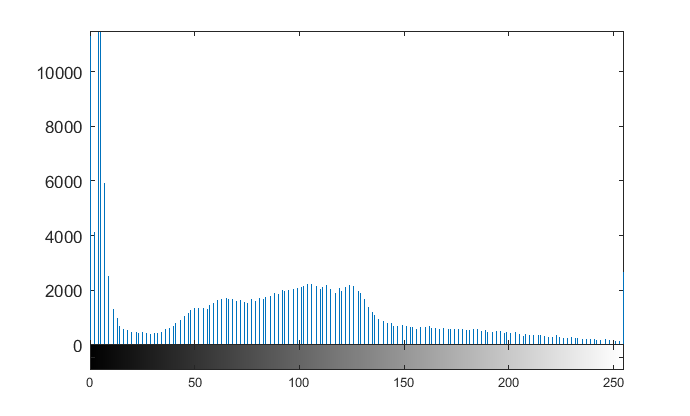

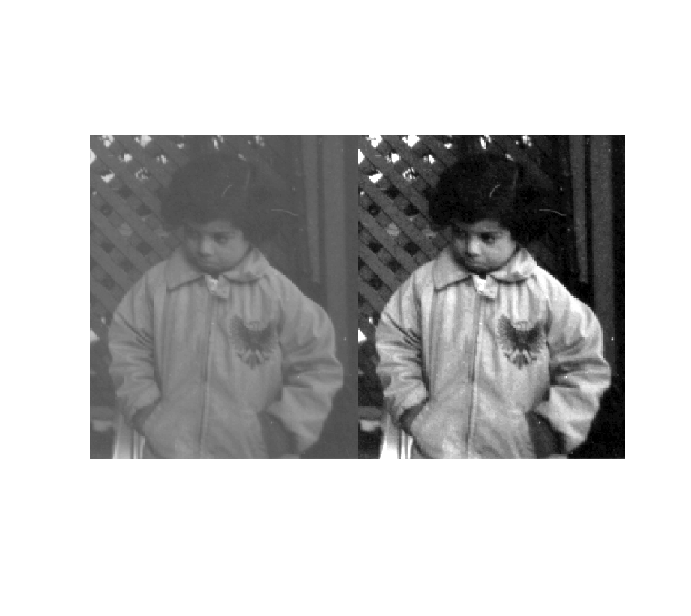

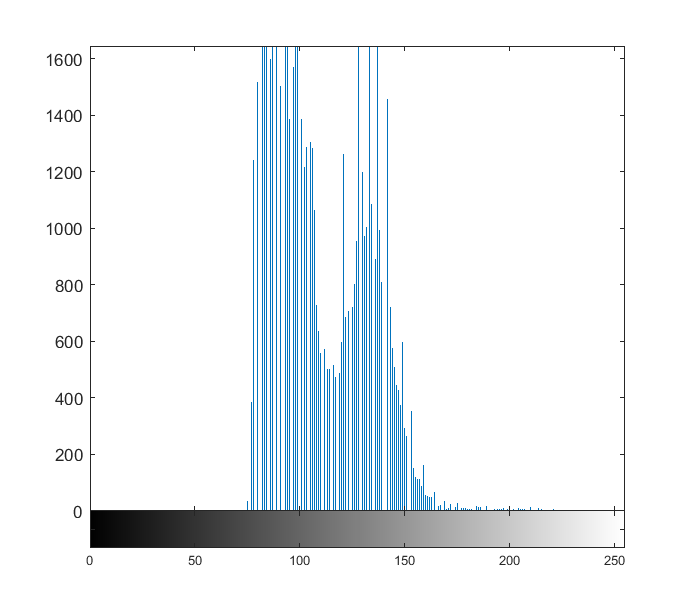

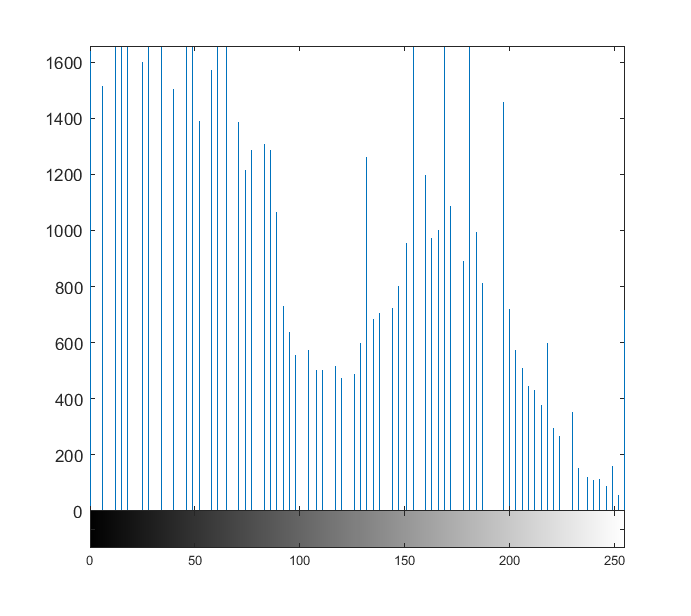

imhist(img_adj)

**Gamma Correction**

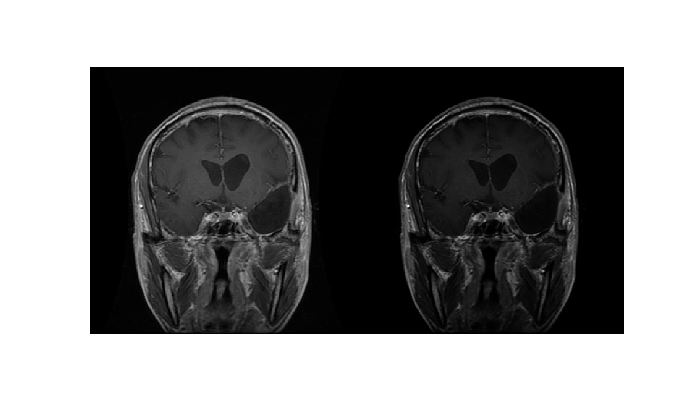

img_gamma= imadjust(img_gray,[],[],1.6);
montage({img_gray, img_gamma})

**Histogram Equalization**

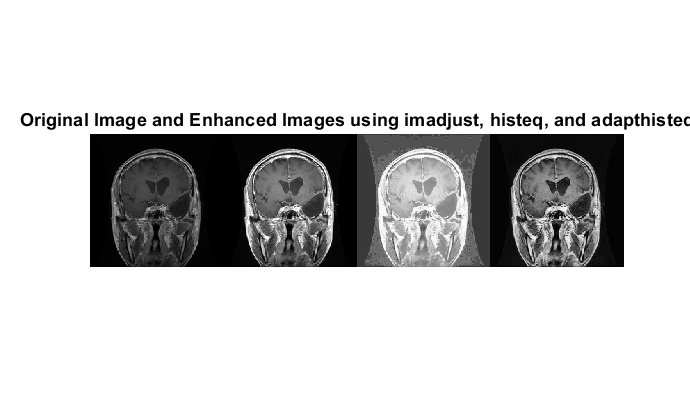

img_hist=histeq(img_gray);
img_hist_ada= adapthisteq(img_gray);
montage({img_gray,  img_adj, img_hist, img_hist_ada,}, 'Size', [1,4])
title("Original Image and Enhanced Images using imadjust, histeq, and adapthisteq")

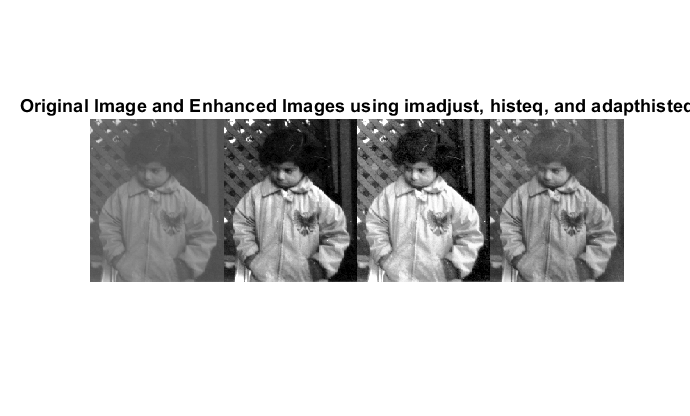

pout = imread("pout.tif");
pout_imadjust = imadjust(pout);
pout_histeq = histeq(pout);
pout_adapthisteq = adapthisteq(pout);
montage({pout,pout_imadjust,pout_histeq,pout_adapthisteq},"Size",[1 4])
title("Original Image and Enhanced Images using imadjust, histeq, and adapthisteq")

imhist(img_gray)

imhist(img_adj)

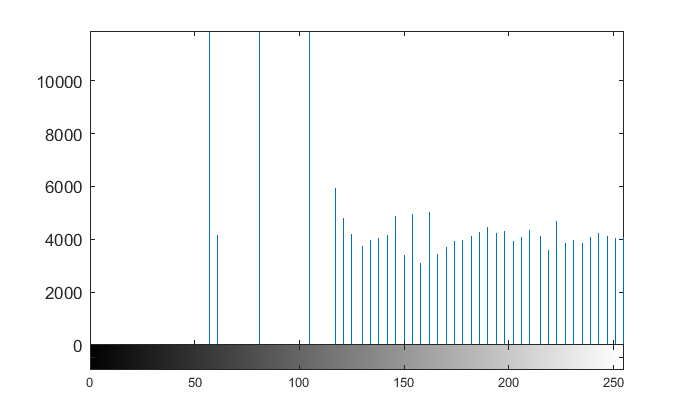

imhist(img_hist)

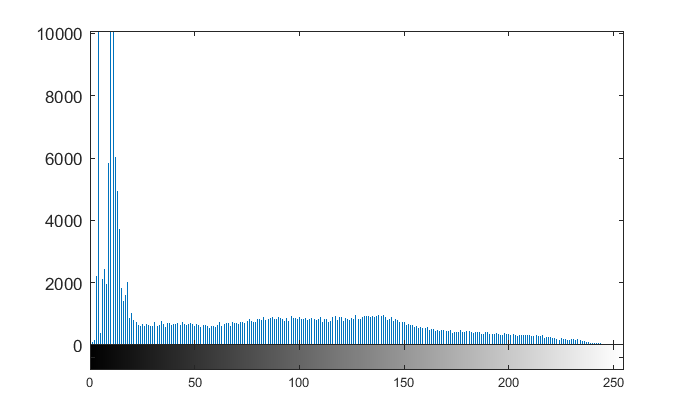

imhist(img_hist_ada)

**Brightening**

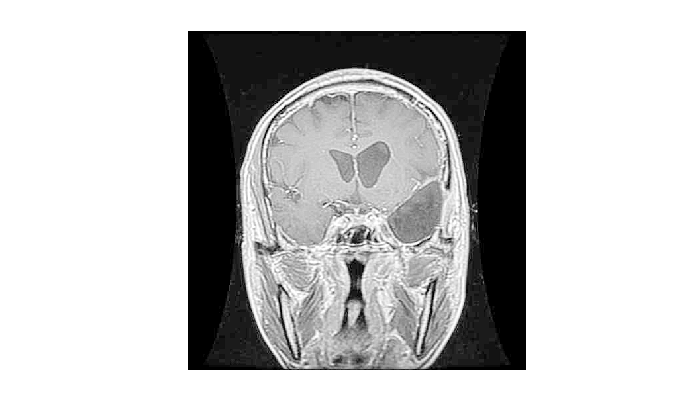

img_bright= imlocalbrighten(img_gray);
imshow(img_bright)

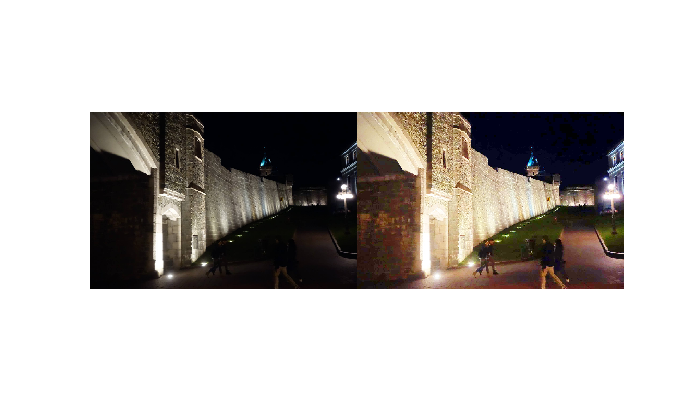

A = imread('lowlight_2.jpg');
B = imlocalbrighten(A, 0.8);
montage({A,B})

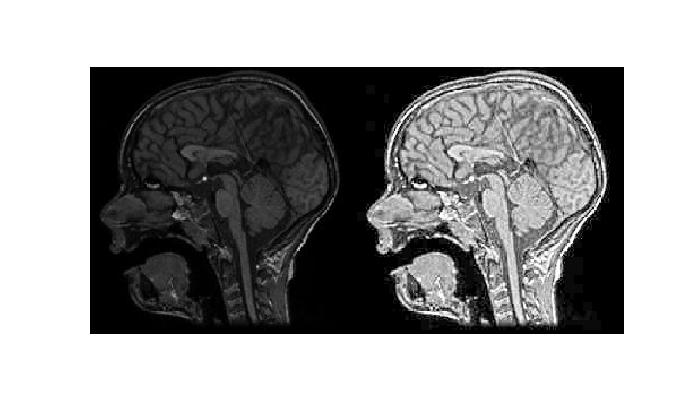

mri= imread('Tr-no_0044.jpg');
mrib= imlocalbrighten(mri);
montage({mri, mrib})

**Sharpening**

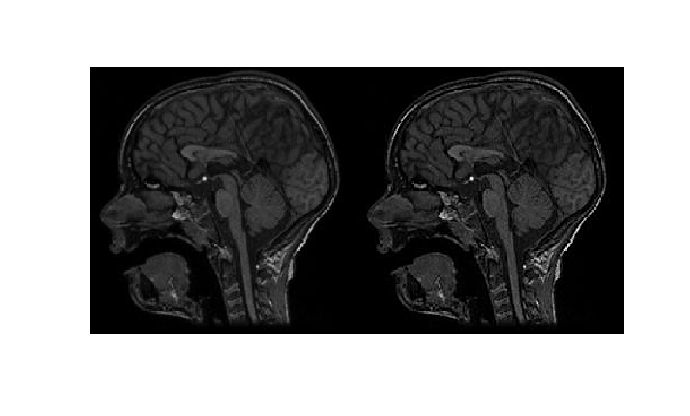

img_sharp = imsharpen(mri);
montage({mri,img_sharp})